先手动加载MAT文件后再运行本脚本

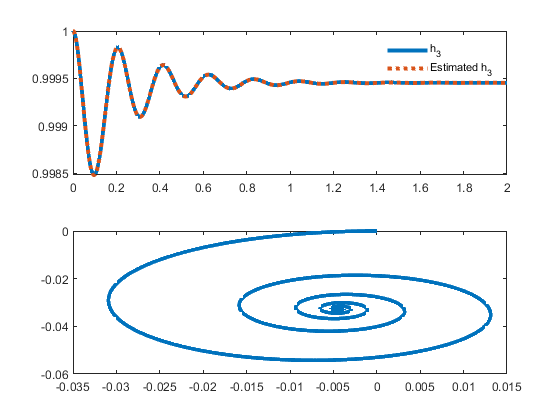

load plot_data.mat
t = out.h3_es.Time;
h3_estimate = out.h3_es.Data;
h3_real = out.n3_real.Data(:,3);
h1_real = out.n3_real.Data(:,1);
h2_real = out.n3_real.Data(:,2);

figure(1)
% h3对比图
subplot(2,1,1)
plot(t,h3_real,"LineWidth",3,'Color',[0 0.4470 0.7410]);
hold on
plot(t,h3_estimate,'LineStyle',":",'LineWidth',3,'Color',[0.8500 0.3250 0.0980]);
legend('h_3','Estimated h_3','box','off')
%h1 h2平面轨迹图
subplot(2,1,2)
plot(h2_real,h1_real,"LineWidth",3,'Color',[0 0.4470 0.7410])